% Sangu Meshing Code
clearvars; clc;

addpath('..')
addpath(genpath('../utilities/'))
addpath(genpath('../datasets/'))
addpath(genpath('../m_map/'))

## STEP 1: set mesh extents and set parameters for mesh.

load("G:\My Drive\Google Drive - VirginiaTech\OneDrive - Virginia Tech\03_Research\Hydrodynamic\CPBMeshFinal\Data\mat\AtlanticOcean_2DDomain.mat", 'model_domain')

min_el    = 1750;
max_el    = [30000,-inf,-2500; 17500,-2500,-1000; 12500,-1000,-500; 7500,-500,-100; 5000,-100,-50; 2500,-50,5; 7500,5,50; 12500,50,+inf]; 
% max_el    = 10000; 
grade     = [0.10,-inf,-2500; 0.10,-2500,-1000; 0.10,-1000,-500; 0.10,-500,-100; 0.10,-100,50; 0.1,-50,10; 0.125,10,50; 0.15,50,+inf]; 
% grade     = 0.5; 
R         = 3;    	

## STEP 2: specify geographical datasets and process the geographical data

## to be used later with other OceanMesh classes...

coastline = 'AltanticShoreline' %'Sangu_Streamline_v2'; % 'GSHHS_f_L1'; 'BD_Coast+Sangu_MainChannel';

coastline = 'AltanticShoreline'

demfile   = 'gebco_2023_n60.0_s5.0_w-102.0_e-18.0.nc';
gdat = geodata('shp',coastline,'bbox',model_domain,'dem',demfile,'h0',min_el);

Read shapefile with shaperead
Partitioning the boundary into islands, mainland, ocean
Smoothing coastline with 5 point window
Read shapefile with shaperead
Partitioning the boundary into islands, mainland, ocean
    {'Read in meshing boundary: '}    {'AltanticShoreline'}



Read in demfile gebco_2023_n60.0_s5.0_w-102.0_e-18.0.nc


## STEP 3: create an edge function class

fh = edgefx('geodata',gdat,... %% 'max_el_ns',max_el_ns,
    'fs',R,'max_el',max_el,'g',grade);

Building feature size function...
Memory management: number of loops in dpoly = 1
Elapsed time is 20.402702 seconds.
--------------------------------------------------
Releasing individual edge functions from memory...
--------------------------------------------------
Relaxing the mesh size gradient
Gradient relaxing converged!
Finalized edge function!


## STEP 4: Pass your edgefx class object along with some meshing options and

build the mesh...

mshopts = meshgen('ef',fh,'bou',gdat,'plot_on',1,'nscreen',5,'proj','trans');

Current mapping parameters -
 Projection: Transverse Mercator  (function: mp_tmerc)     
 longitudes: -136.8343     -17.78017 (centered at -77.3073)
 latitudes: 0.99361      62.5038                           
 Rectangular border: off                                   


Forming initial point distribution...
    for box #1
Using 0 fixed points.
Number of initial points after rejection is 438512
Elapsed time is 51.172203 seconds.
 ------------------------------------------------------->
Begin iterating...
Elapsed time is 7.039007 seconds.
Elapsed time is 5.729428 seconds.
Elapsed time is 5.664299 seconds.
Elapsed time is 5.776744 seconds.
Iteration =5
Number of nodes is 438512
Mean mesh quality is 0.86073
Min mesh quality is 0.02194
3rd sigma lower mesh quality is 0.49169
Elapsed time is 7.453237 seconds.
Elapsed time is 5.773819 seconds.
Elapsed time is 5.942530 seconds.
Elapsed time is 5.961733 seconds.
Elapsed time is 5.733335 seconds.
Iteration =10
Number of nodes is 438512
Mean mesh quality is 0.89129
Min mesh quality is 0.02199
3rd sigma lower mesh quality is 0.58631
Elapsed time is 7.089934 seconds.
Elapsed time is 5.961903 seconds.
Elapsed time is 5.766885 seconds.
Elapsed time is 5.776235 seconds.
Elapsed time is 5.713182 seconds.
Iteration =15

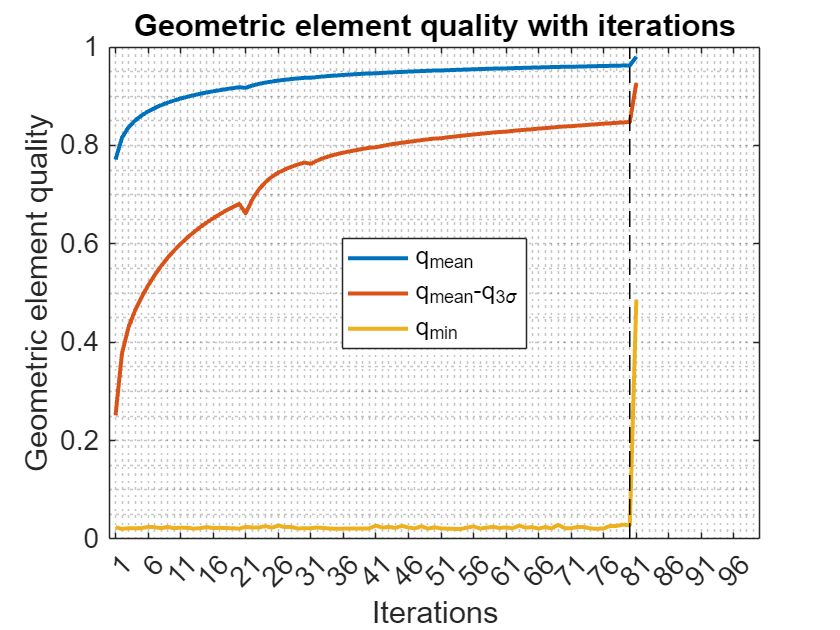

mshopts = mshopts.build;

## STEP 5: Plot it and write a triangulation fort.14 compliant file to disk.

Get out the msh class and put on nodestrings

Current mapping parameters -
 Projection: Transverse Mercator  (function: mp_tmerc)  
 longitudes: -99.5507     -19.3533 (centered at -59.452)
 latitudes: 6.94748       58.603                        
 Rectangular border: off                                


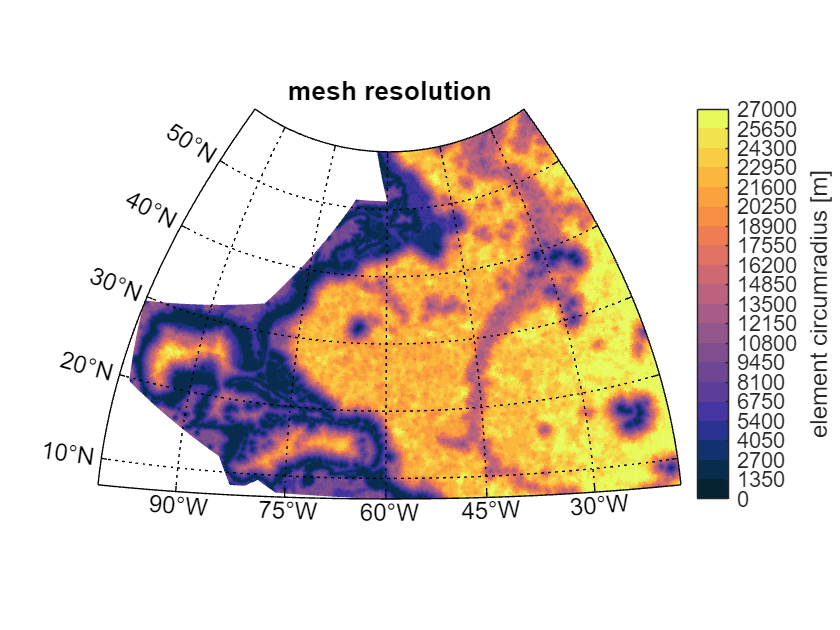

m = mshopts.grd;
% m = make_bc(m,'auto',gdat,'distance'); % make the boundary conditions
% plot(m,'type','bd');
% if you want to write into fort.14...
% plot(m,'type','resomesh','colormap',[20 0 400])
plot(m,'type','resomesh','colormap',[20 0 27000])

%write(m,'G:\My Drive\Deflt3D_BoB\Data\grid\grid\BoBv5_100_3000_0015_adcric');

## STEP 6: Example of plotting a subdomain with bcs

% write(m,'E:\ChesapeakeModel\Data\MeshCreation\gridsOM2D\MinRes250mMin\cpb_lowres_adcric');

% m = mshopts.grd ;
% plot resolution on the mesh
% plot(m,'type','resomesh','colormap',[10 0 500])
